% Call the script to get the waveforms and the CFD Look Up Table
% waveforms = f01_pmtCFDWaveforms();
% waveform = waveforms(:,1);
clear all;
root_data = readmatrix("C:\Users\miech\Documents\HyperK\Repozytoria\mpmt_teststand\waveforms.csv");
waveforms = root_data';
waveforms(isnan(waveforms)) = 0;

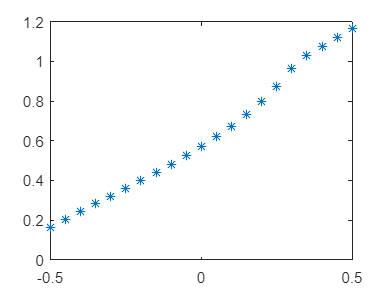

waveform = waveforms(1:32,10);

[wut_cr_lut_data, uvic_cfd_lut_data, uvic_cfd_true_data, uvic_amp_lut_data]  = f00_pmtCFDAlgorithmLUT();
plot(uvic_cfd_true_data, uvic_cfd_lut_data, "*")

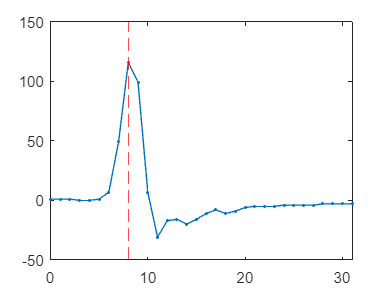

% Find peak time beans

threshold = 20;
% for peak finding, the baseline is assumed to be zero

baseline = 0;

% threshold is the minimum positive signal above baseline
below = (waveform(1) - baseline) <= threshold;
peak_timebins = [];
max_val = 0;
max_timebin = -1;

for k = 1 : length(waveform)
    if (below && (waveform(k) - baseline > threshold))
        below = false;
        max_val = 0;
        max_timebin = -1;
    end
    if ~below
        if (waveform(k) - baseline > max_val)
            max_val = waveform(k) - baseline;
            max_timebin = k - 1;
        end
        if (waveform(k) - baseline <= threshold)
            below = true;
            peak_timebins = [peak_timebins; max_timebin];
        elseif (k == length(waveform))
            peak_timebins = [peak_timebins; max_timebin];
        end
    end
end
plot(0:length(waveform)-1, waveform, ".-")
xline(peak_timebins, "--r"); hold off;

analysis_offset = peak_timebins - 7;
adcs = waveform(analysis_offset + 1:analysis_offset + 10);

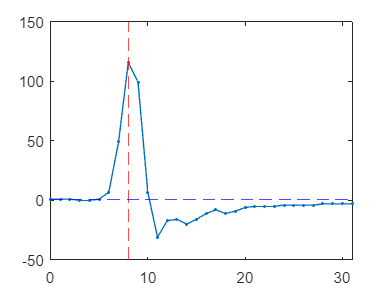

% Calculate CFD
%     # Use a cfd like algorithm with delay d = 2, multiplier c = -2
c = -2;
d = 2;

%     # for cfd just use the average of the first 3 adcs as the baseline
baseline = (adcs(1) + adcs(2) + adcs(3)) / 3.;
yline(baseline, "--b");

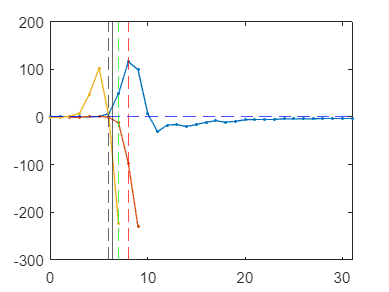

correct_amp = 2.1082

%     # the amplitude is found by adding the highest 3 adcs and subtracting the baseline
%     # amp = (baseline - np.min(adcs)) / 100.
sorted_vals = sort(adcs - baseline, 'descend');
n_largest_vals = sorted_vals(1:3);
amp = sum(n_largest_vals);

%     # converting to positive going pulses
for k = d + 1 : length(adcs)
    reversed(k - d) = c * (adcs(k-d) - baseline);
    cfd_waveform(k-d) = (adcs(k) - baseline) + c * (adcs(k-d) - baseline);
end

plot(0:length(waveform)-1, waveform, ".-", ...
    2:length(reversed)+1, reversed, ".-", ...
    0:length(cfd_waveform)-1, cfd_waveform, ".-")
xline(peak_timebins, "--r");
yline(baseline, "--b");

%     # find largest swing zero crossing
max_diff = 0;
i_md = -1;
for iv  = 2 : length(cfd_waveform)
    if cfd_waveform(iv - 1) > 0. && cfd_waveform(iv) < 0.
        if cfd_waveform(iv - 1) - cfd_waveform(iv) > max_diff
            max_diff = cfd_waveform(iv - 1) - cfd_waveform(iv);
            i_md = iv;
        end
    end
end
xline(i_md - 1, "--g")

if i_md > -1
    x0 = (i_md - 1) - 1;
    y0 = cfd_waveform(i_md - 1);
    x1 = (i_md) - 1;
    y1 = cfd_waveform(i_md);

%         # using a linear interpolation, find the value of x for which y = 0
    x = x0 - (x1 - x0) / (y1 - y0) * y0;
    % x = x0 + y0 * (x1 - x0) / (y0 - y1);
%         # apply offset assuming sigma = 0.96 (see try_cfd.ipynb)
    % x = x - 0.5703;
    xline(x, "--p")
%         # apply a correction
    apply_correction = true;
    offset = 5.;
    delta = x - offset;
    t = [];
    if apply_correction
        if (uvic_cfd_lut_data(1) < delta) && (delta < uvic_cfd_lut_data(end))
            correct_t = interp1(uvic_cfd_lut_data, uvic_cfd_true_data, delta);
            t = offset + correct_t;
        elseif delta < uvic_cfd_lut_data(1)
            delta = delta + 1;
            if (uvic_cfd_lut_data(1) < delta) && (delta < uvic_cfd_lut_data(end))
                correct_t = interp1(uvic_cfd_lut_data, uvic_cfd_true_data, delta);
                t = offset - 1 + correct_t;
            end
        elseif delta > uvic_cfd_lut_data(end)
            delta = delta - 1;
            if (uvic_cfd_lut_data(1) < delta) && (delta < uvic_cfd_lut_data(end))
                correct_t = interp1(uvic_cfd_lut_data, uvic_cfd_true_data, delta);
                t = offset + 1 + correct_t;
            end
        end
        xline(t+1)
    end
    if isempty(t)
        t = x - 0.5703;
        amp = amp / 2.118;  % average correction
    else
        correct_amp = interp1(uvic_cfd_true_data, uvic_amp_lut_data, correct_t)
        amp = amp / correct_amp;
    end

    t = t + analysis_offset;
else
    t = -999;
    amp = -999;
end